clc;
close all;
clear variables;

ma = [20; 30]; 
mb = [3; 1];

sigma_a = [3; 2.3];
sigma_b = [2.7; 2];

rho_a = 0.8;
rho_b = -0.7;

num_a = 5000;
sum_b = 500;

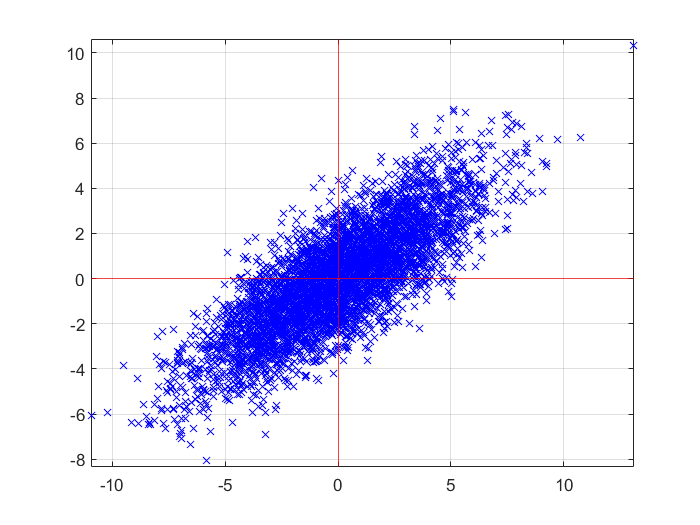

A = Samples(ma, sigma_a, rho_a,  num_a);
% B = Samples(mb, sigma_b, rho_b, sum_b);

figure();
A.samples = A.samples - A.M;
A.plot('bx'); 
grid on; hold on; axis equal;
xline(0, 'r');
yline(0, 'r');

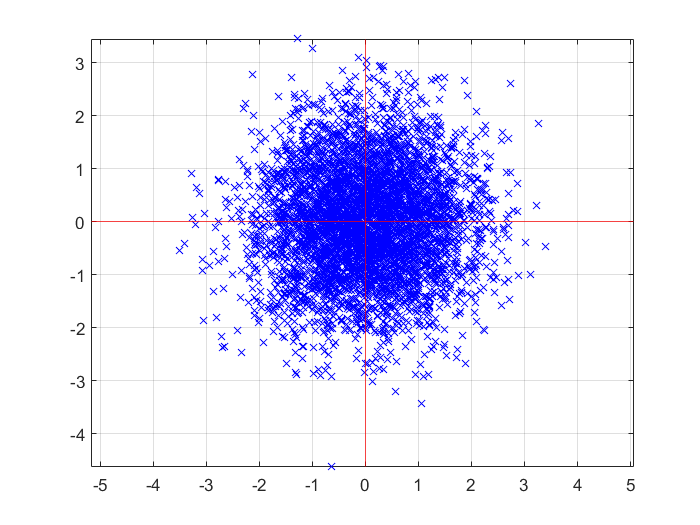

figure();
[F, L] = eig(A.cov_mat);
A.samples = (F * L^(-0.5))' * A.samples;
A.plot('bx');
grid on; hold on; axis equal;
xline(0, 'r');
yline(0, 'r');

figure();
A.samples = F * L^0.5 * A.samples;
A.plot('bx');
grid on; hold on; axis equal;
xline(0, 'r');
yline(0, 'r');